Reading in data

imread("data32\test\animal animal_faces cat cat_face\0BGPHALKEI6K.jpg", "jpg")

ans = 32×32×3 uint8 array
ans(:,:,1) =

   164   171   166   159   159   150   150   145   137   140   117    76    61    72    84    86    90    90    90    88    89    87    87    89    88    90    88    87    84    76    77    72
   170   172   169   158   159   155   150   143   140   141   116    75    59    71    83    86    87    88    89    88    90    92    92    88    90    93    92    86    84    82    79    71
   152   173   172   164   157   150   148   141   137   139   114    76    62    71    80    82    81    80    86    92    92    88    90    93    90    88    82    83    80    83    69    71
   150   172   165   160   156   151   146   142   136   140   116    76    62    72    79    82    80    80    85    89    90    95    95    87    85    88    81    80    76    72    72    70
   149   169   167   158   156   147   139   138   135   140   118    76    60    71    81    83    79    82    85    89    91    92    90    86    81    76    87   137   136    74    65  


imagefiles = dir("data32\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1661×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data32\test\animal animal_faces cat cat_face"

filepath = "data32\test\animal animal_faces cat cat_face"

for ii=1:50
   currentfilename = imagefiles(ii).name;
   currentimage = imread(filepath + "\" +  currentfilename);
   images{ii} = currentimage;
end

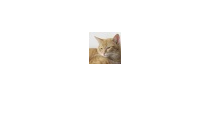

imshow(images{1})

Reproduce image

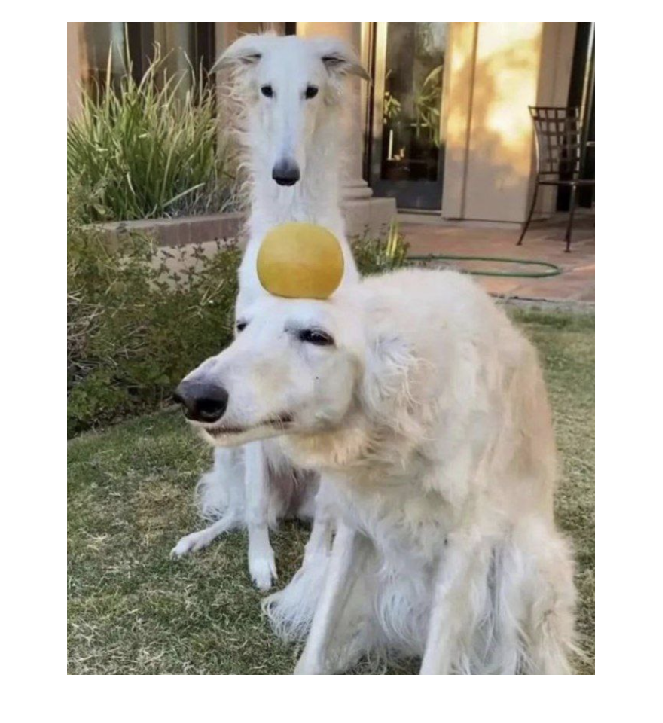

targetImage = imread("dogdogorange.png");

imshow(targetImage)


[l, h, d] = size(targetImage)

l = 867

h = 701

d = 3

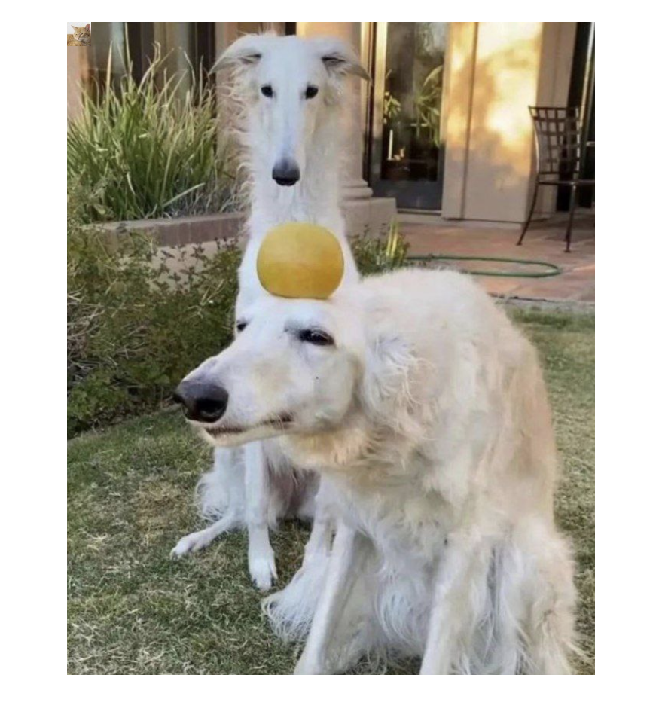


targetImage(1:32, 1:32, :) = images{1};

imshow(targetImage)

Image Segmentation

Use kmeans with random clustters to segment the image 

segmentedImage = targetImage

segmentedImage = 867×701×3 uint8 array
segmentedImage(:,:,1) =

   236   230   232   231   226   224   229   229   232   235   234   233   233   234   233   228   230   231   227   228   229   233   233   234   232   229   237   234   234   236   237   237   108   109   106   102    99    97    97    97    98   100   100   100   100   100   100   100    99    98    98   100   102   105   106   108   111   115   118   129   142   150   150   148   147   147   148   146   140   131   123   119   114    96    72    65    82   117   124    90    54    42    41    41    40    40    40    41    42    42    43    43    43    45    46    43    46    56    67    71    66    63    64    61    57    59    60    58    59    61    63    62    65    70    81   100   117   123   122   120   120   119   114   109   106   107   109   106   100    98   104   116   125   127   123   119   118   119   117   117   119   119   116   113   111   111   111   111   108   106   104   103   103   104   105   103


for i = 1:3
segmentedImage(:,:,i) = segmentImage(targetImage(:,:,i))

end

segmentedImage = 867×701×3 uint8 array
segmentedImage(:,:,1) =

   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13 

segmentedImage = 867×701×3 uint8 array
segmentedImage(:,:,1) =

   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13 

segmentedImage = 867×701×3 uint8 array
segmentedImage(:,:,1) =

   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   43   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   19   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28   28    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9    9   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13 

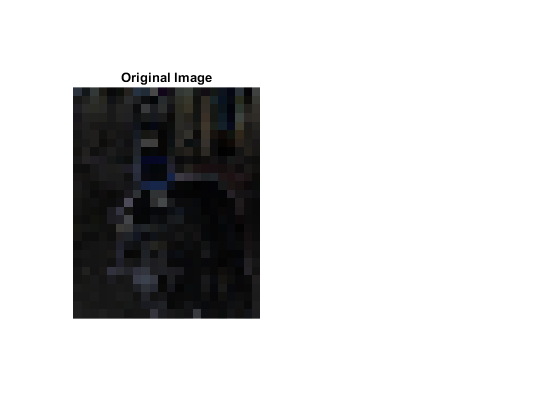


figure;
subplot(1, 2, 1);
imshow(segmentedImage);
title('Original Image');

Segment image into 32 bit chunks and standard deviate colours

function output = segmentImage(img)

blockSize = [32, 32]; % går att byta
output = blockproc(img, blockSize, @processBlock);

end

%skum dokumentation
function outBlock = processBlock(blockStruct)
    originalBlock = blockStruct.data;
        stdValue = std2(originalBlock);
        outBlock = stdValue * ones(size(originalBlock), 'like', originalBlock);
end
